%#ok<*UNRCH> 
% równość z zerem jest mierzona domyślnie z dokładnością 10^-10, można to
% tu zmienić
dokladnosc = 10;

% VVV parę linijek komentarza które można usunąć po skopiowaniu tego pliku VVV
% Najlepiej to się czyta dla trybu "output inline" lub "output to the
% right", ale można dodać władny tekst wyjaśniający (live editor>text>text),
% i użyć "hide code"
% Możliwe że nie wszystko będzie w pełni poprawne
% Wiedza kodu *nie pomaga* w zrozumieniu zagadnienia (co się liczy do punktacji), polecam poszukać na
% necie/chatGPT. Jest to "problem" ze wszystkimi labami które przeglądałem.

% stwórz macierz
N=20;
macierz_analizy=zeros(N,N);
for k=0:(N-1)
    if k==0
        s=sqrt(1/N);
    else
        s=sqrt(2/N);
    end
    for n=0:(N-1)
        macierz_analizy(k+1,n+1)=s*cos(pi*(k/N)*(n+0.5));
    end
end
% sprawdź czy jest ortonormalna
for k=1:N
    for n=1:N
        if not(k==n)
            if not(0==round(macierz_analizy(k,:)*macierz_analizy(n,:)',dokladnosc))
                "Wiersz "+k+" i "+n+" nie są ortonormalne z dokładnością 10^-"+dokladnosc
            end
        end
    end
end

% zad.2
% sprawdź czy jest równa z identycznościową
macierz_syntezy = macierz_analizy.';
matlab_moment=(macierz_syntezy*macierz_analizy==eye(N,N)); % komórka 1,1 jest równa 1 
"Jeżeli jest to true, to S*A==I: "+matlab_moment(1,1)

ans = "Jeżeli jest to true, to S*A==I: true"

clear matlab_moment;
% sygnał losowy
x=randn(N,1);
X=macierz_analizy*x;
x_prim=macierz_syntezy*X;
% jak widać różnice są rzędu 10^-15
"Średnia różnica sygnału po rekonstrukcji to: "+sum(abs((x-x_prim))/N)

ans = "Średnia różnica sygnału po rekonstrukcji to: 1.3718e-15"

% Dla dociekliwych
macierz_losowa_analizy = randn(N,N);
% losowa macierz
for k=1:N
    for n=1:N
        if not(k==n)
            % Praktycznie zero szans na ortonormalność. Dlatego output jest
            % zablokowany ";"
            if not(1==round(macierz_losowa_analizy(k,:)*macierz_losowa_analizy(n,:)',dokladnosc))
                "Wiersz "+k+" i "+n+" nie są ortonormalne z dokładnością 10^-"+dokladnosc;
            end
        end
    end
end
macierz_losowa_syntezy = inv(macierz_losowa_analizy);
X=macierz_losowa_analizy*x;
x_prim=macierz_losowa_syntezy*X; %#ok<MINV> 
"Średnia różnica sygnału po rekonstrukcji to: "+sum(abs((x-x_prim))/N)

ans = "Średnia różnica sygnału po rekonstrukcji to: 2.9195e-15"

% Jest inv zamiast .' tutaj
macierz_losowa_syntezy = inv(macierz_losowa_analizy);
matlab_moment=(macierz_syntezy*macierz_losowa_analizy==eye(N,N)); % komórka 1,1 jest równa 1 
"Jeżeli jest to true, to S*A==I: "+matlab_moment(1,1)

ans = "Jeżeli jest to true, to S*A==I: false"

clear matlab_moment;

% popsute DCT
macierz_analizy_fake=zeros(N,N);
for k=0:(N-1)
    if k==0
        s=sqrt(1/N);
    else
        s=sqrt(2/N);
    end
    % calc
    for n=0:(N-1)
        macierz_analizy_fake(k+1,n+1)=s*cos(pi*((k+0.25)/N)*(n+0.5));
    end
end
for k=1:N
    for n=1:N
        if not(k==n)
            % błędy na poziomie 10^-2, 10^-1. Założone ";", ale można się
            % go pozbyć. Odkomentowanie 
            % macierz_analizy_fake(k,:)*macierz_analizy_fake(n,:)'
            % wydrukuje skalę błedu, jako różnicę od 0.
            if not(0==round(macierz_analizy_fake(k,:)*macierz_analizy_fake(n,:)',dokladnosc))
                "Wiersz "+k+" i "+n+" nie są ortonormalne z dokładnością 10^-"+dokladnosc;
            end
        end
    end
end


% zad. 3
N = 100;
czestotliwosc_probkowania = 1000;
amp1=50;
freq1=50;
amp2=100;
freq2=100;
amp3=150;
freq3=150;
% zwiększyć f2 o 5 Hz?
if false
    freq2=freq2+5;
end
% zwiększyć wszystko o 2.5 Hz?
if false
    freq1=freq1+2.5;
    freq2=freq2+2.5;
    freq3=freq3+2.5;
end
timesteps = 0:1/czestotliwosc_probkowania:(N-1)/czestotliwosc_probkowania;
x = amp1*sin(timesteps*freq1)+amp2*sin(timesteps*freq2)+amp3*sin(timesteps*freq3);
x=x.';
macierz_analizy = zeros(N,N);
for k=0:(N-1)
    if k==0
        s=sqrt(1/N);
    else
        s=sqrt(2/N);
    end
    for n=0:(N-1)
        macierz_analizy(k+1,n+1)=s*cos(pi*(k/N)*(n+0.5));
    end
end
macierz_syntezy=macierz_analizy.';
for i =1:N
    % Wyświetl wiersze i kolumny macierzy?
    if false
        macierz_analizy(i,1:N)
        macierz_syntezy(1:N,i).'
    end
end
% wyświetl macierz analizy i macierz syntezy jako "obrazki"

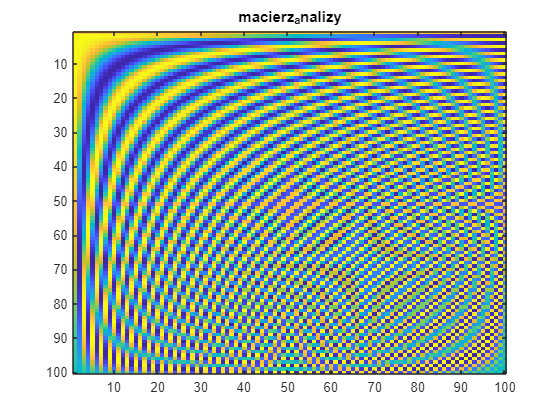

% Create imagesc of macierz_analizy
im = imagesc(macierz_analizy);

% Add title
title("macierz_analizy")

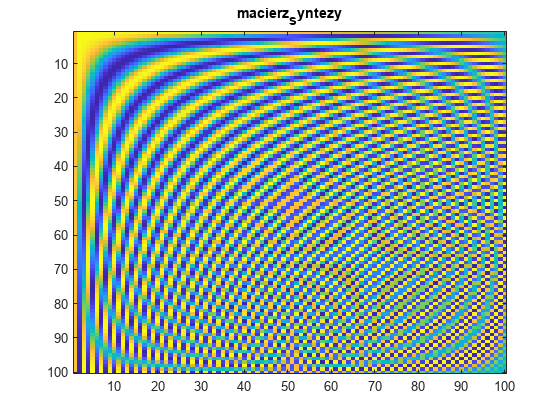

% Create imagesc of macierz_syntezy
im2 = imagesc(macierz_syntezy);

% Add title
title("macierz_syntezy")

y=macierz_analizy*x;

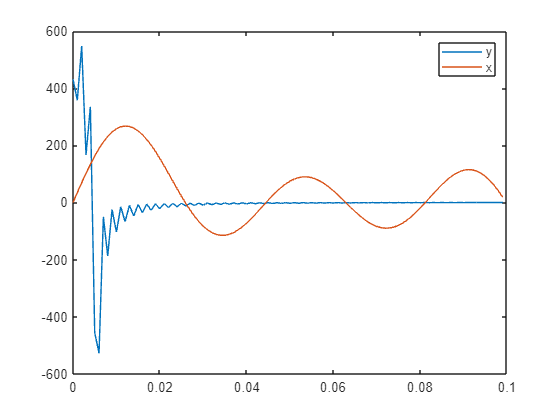

figure
% Create plot of timesteps and y
plot(timesteps,y,"DisplayName","y");

hold on
% Create plot of timesteps and x
plot(timesteps,x,"DisplayName","x");
hold off

legend

frequency_timesteps=(0:N-1)*czestotliwosc_probkowania/N;

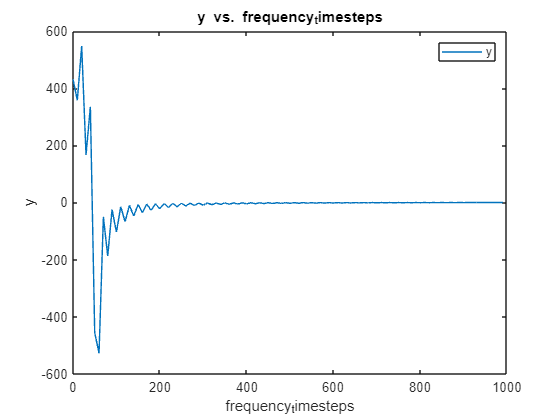

% Create plot of frequency_timesteps and y
h2 = plot(frequency_timesteps,y,"DisplayName","y");

% Add xlabel, ylabel, title, and legend
xlabel("frequency_timesteps")
ylabel("y")
title("y vs. frequency_timesteps")
legend

% zrekonstruuj sygnał
x_prim=macierz_syntezy*y;

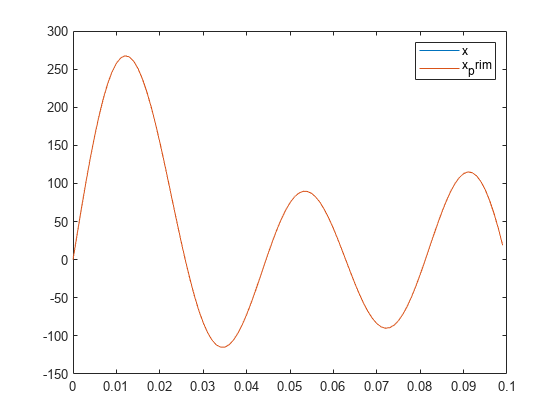

figure
% Create plot of timesteps and x
plot(timesteps,x,"DisplayName","x");

hold on
% Create plot of timesteps and x_prim
plot(timesteps,x_prim,"DisplayName","x_prim");
hold off

legend

% zad. 4
[x ,fs] =audioread("mowa.wav"); 

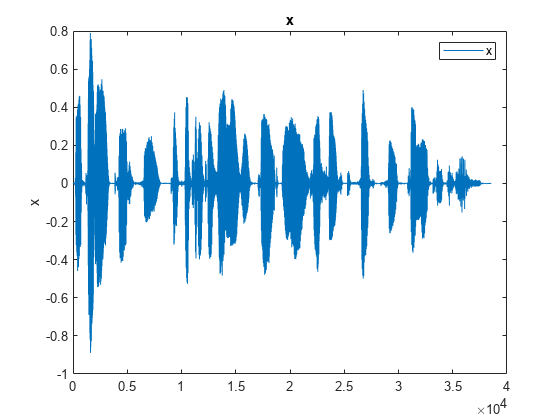

% Create plot of x
h = plot(x,"DisplayName","x");

% Add ylabel, title, and legend
ylabel("x")
title("x")
legend

% stwórz macierz analizy
N=256;
macierz_analizy=zeros(N,N);
for k=0:(N-1)
    if k==0
        s=sqrt(1/N);
    else
        s=sqrt(2/N);
    end
    for n=0:(N-1)
        macierz_analizy(k+1,n+1)=s*cos(pi*(k/N)*(n+0.5));
    end
end
% można wpisać własne wartości tutaj
punkty_probek = [123,1680,4666,7000,10000,12345,20000,23456,30000,34556];
skala_hertz = 0:fs/(N-1):fs;

numer_probki=9;
probka = x(punkty_probek(numer_probki):punkty_probek(numer_probki)+255);
y=macierz_analizy*probka;


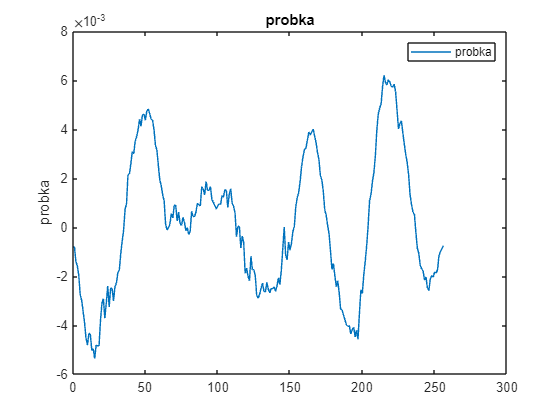

% Create plot of probka
h3 = plot(probka,"DisplayName","probka");

% Add ylabel, title, and legend
ylabel("probka")
title("probka")
legend

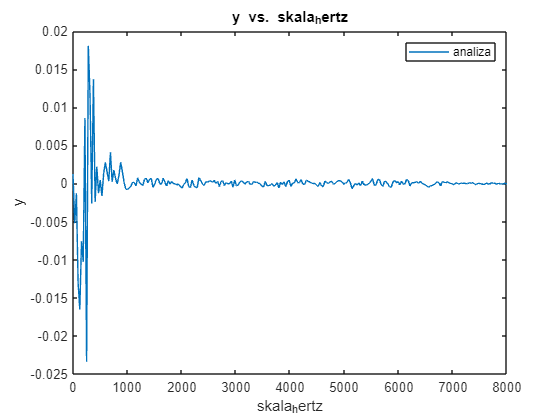

% Create plot of skala_hertz and y
h4 = plot(skala_hertz,y,"DisplayName","y");

% Add xlabel, ylabel, title, and legend
xlabel("skala_hertz")
ylabel("y")
title("y vs. skala_hertz")
legend

legend("analiza")